# Explore Network Explainability Using an App

The question of how a deep learning network makes its decisions is becoming increasingly important as deep networks becomes prevalent in every area of society. Explainability is an area of research which is receiving increasing attention, as such there are many methods developed to provide insight into the predictions a network makes.

This example shows you how to train a network and then explore what the network has learned by using several visualisation techniques. It can be difficult to easily compare these methods, however using an app you can easily compare different deep learning visualisation techniques. Click **Run**   to run the live script. This script will load an image classification data set, construct and train an image classification network, and open an app to explore the network predictions.

This example illustrates several techniques.

#### Occlusion Sensitivity 

Occlusion sensitivity is a simple technique for understanding which parts of an image are most important for a deep network's classification [1]. You can measure a network's sensitivity to occlusion in different regions of the data using small perturbations of the data. 

#### Grad-CAM

Grad-CAM, invented by Selvaraju and coauthors [2], uses the gradient of the classification score with respect to the convolutional features determined by the network in order to understand which parts of the image are most important for classification.

#### Gradient Attribution 

Gradient attribution provides pixel-resolution maps that show which pixels are most important to the network's classification [3]. Intuitively, the map shows which pixels most affect the class score when changed. 

#### Deep Dream 

Deep Dream is a feature visualization technique in deep learning that synthesizes images that strongly activate network layers [4]. By visualizing these images, you can highlight the image features learned by a network. These images are useful for understanding and diagnosing network behaviour.

#### t-SNE

Use t-SNE to visualize the network activations and gain an understanding of how the network responds [5]. You can use t-SNE to visualize how deep learning networks change the representation of input data as it passes through the network layers. 

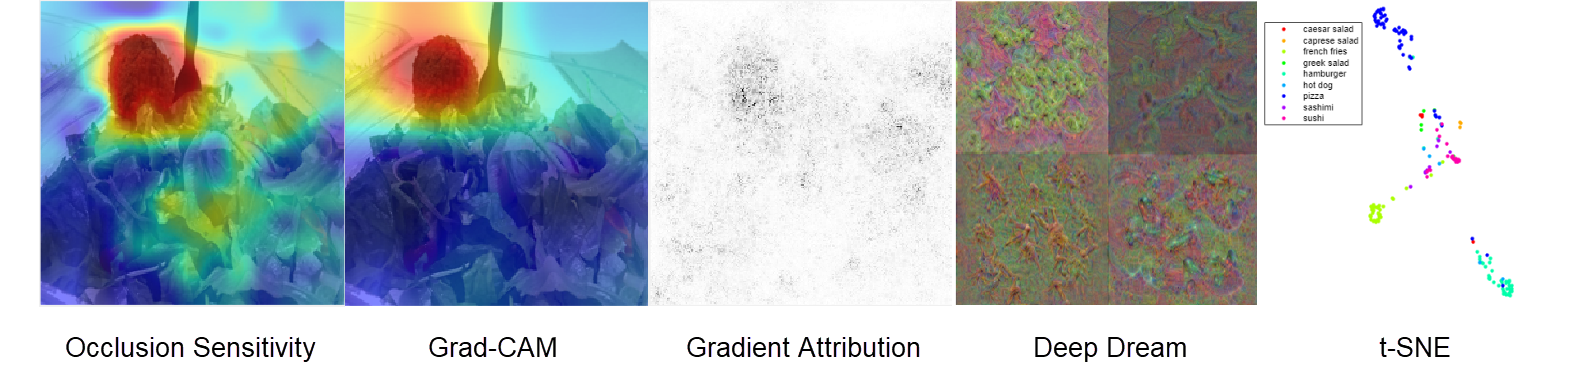

## Load Data

Download and extract the Example Food Image data set. 

rng default
dataDir = fullfile(tempdir,"ExampleFoodImageDataset");
url = "https://ssd.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip";

if ~exist(dataDir,"dir")
    mkdir(dataDir);
end

downloadExampleFoodImagesData(url,dataDir);

This can take several minutes to download...
Download finished...
Unzipping file...
Unzipping finished...
Done.


Create an image datastore using the `imageDatastore` function.

imds = imageDatastore(dataDir, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

imds.Labels = categorical(replace(string(imds.Labels),"_"," "));

Split the data into training and validation sets.

[imdsTrain,imdsVal] = splitEachLabel(imds,0.8,0.2,'randomized');

View the distribution of the class labels. You can see that this data set does not have an even distribution of class labels.

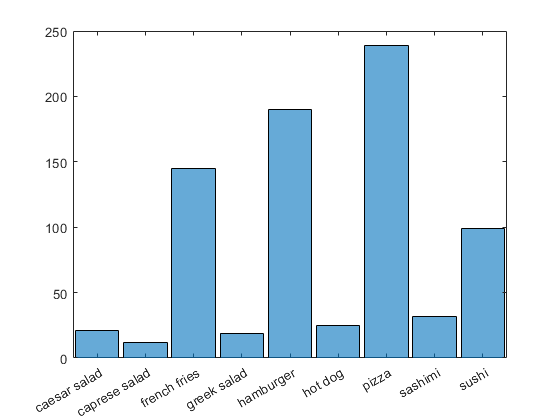

histogram(imdsTrain.Labels)

Load a pretrained GoogLeNet network [6].

net = googlenet;

Resize the images to the input size of the pretrained network.

inputSize = net.Layers(1).InputSize;

augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain);
augimdsVal = augmentedImageDatastore(inputSize,imdsVal);

## Define Network Architecture

To use the pretrained network for transfer learning you must replace the last learnable layer and the final output layer with new layers specific to this data set. Prepare this network programmatically or using Deep Network Designer.

Extract layer graph.

lgraph = layerGraph(net);

Define new layers specific to this data set.

numClasses = numel(categories(imdsTrain.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);

newClassLayer = classificationLayer('Name','new_classoutput');

Replace the current layers with the new layers.

lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);
lgraph = replaceLayer(lgraph,'output',newClassLayer);

## Train Network

Specify the training options. Train for 30 epochs and validate the network once per epoch. Set the learning rate to 0.0001.

valFrequencyEpochs = 1;
miniBatchSize = 50;

numObservations = augimdsTrain.NumObservations;
numIterationsPerEpoch = floor(numObservations/miniBatchSize);
valFrequency = valFrequencyEpochs * numIterationsPerEpoch;

options = trainingOptions('sgdm', ...
    'MaxEpochs',30, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsVal, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the network.

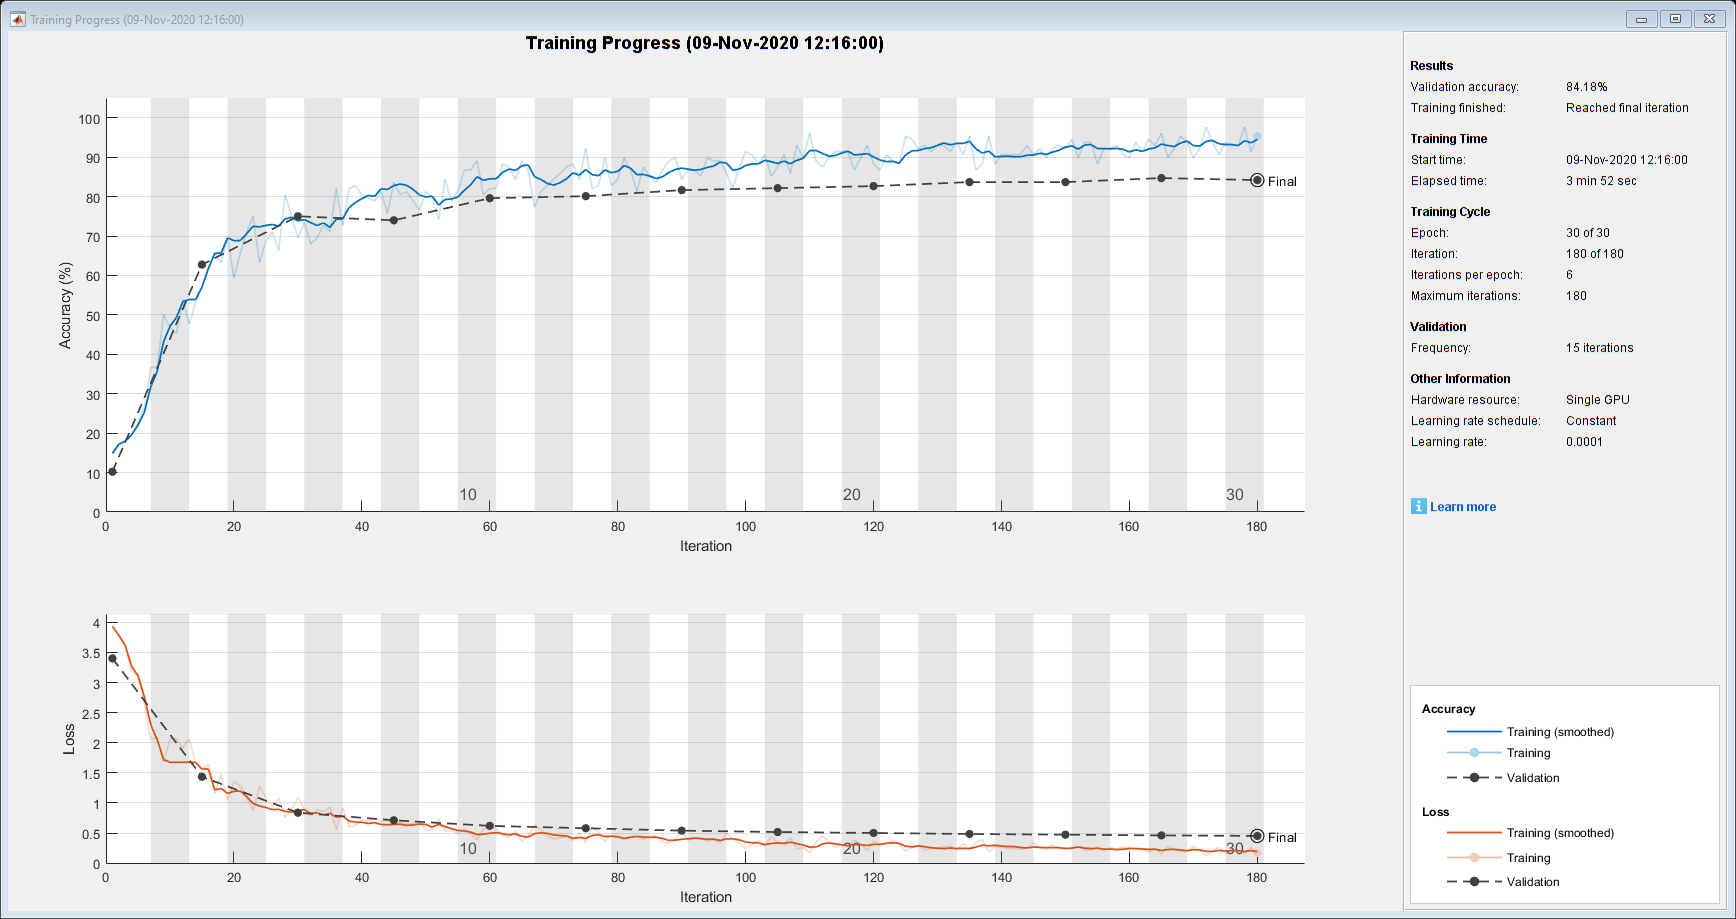

trainedNet = trainNetwork(augimdsTrain,lgraph,options);    

## Open App with Trained Network

There exist many ways to visualize a trained deep learning network. Use an app created using App Designer to interactively compare different visualization techniques.

Understanding Network Predictions for Image Classification (UNPIC) is an app attached as a supporting file and includes several visualisation techniques to help you explore the trained network. This is not an exhaustive list and it is simple to add additional methods using App Designer. Additionally the techniques included all require choices to be made so you are encouraged to take a look at the underlying functions in App Designer and tune the methods to better understand the network.

The app requires a trained network and image data. The image data is used to help explore what the trained network has learned.

UNPIC(trainedNet,imdsVal);

You can use the app to explore and better understand the trained network. For an example showing how to use the app to explain the network, see the supporting live script '`ExploreTrainedFoodClassificationNetwork.mlx`'.

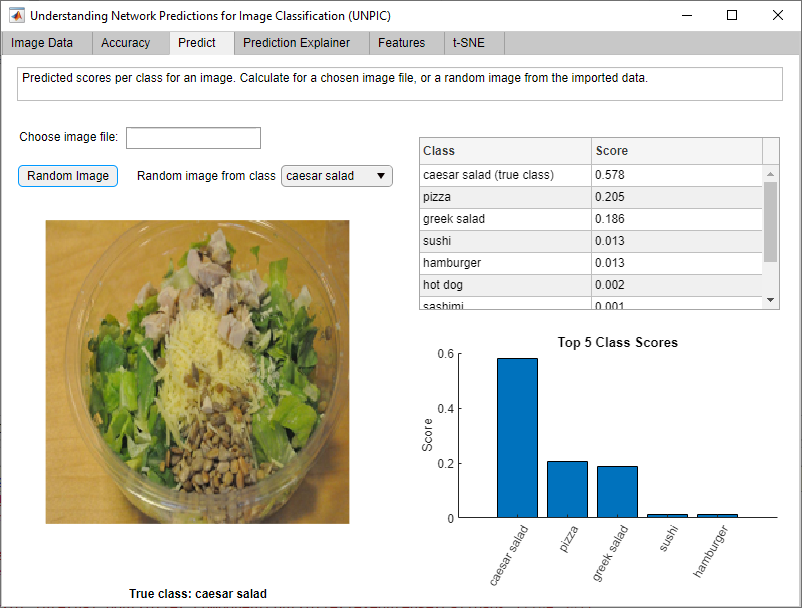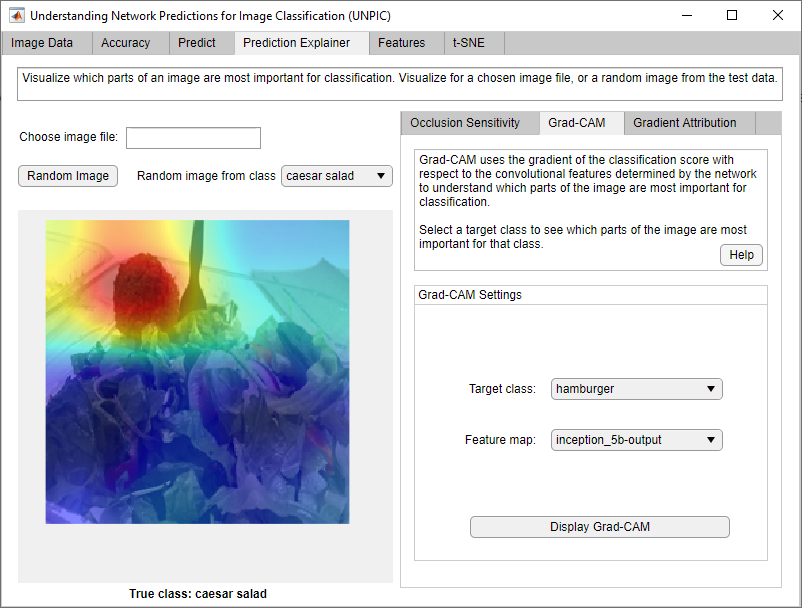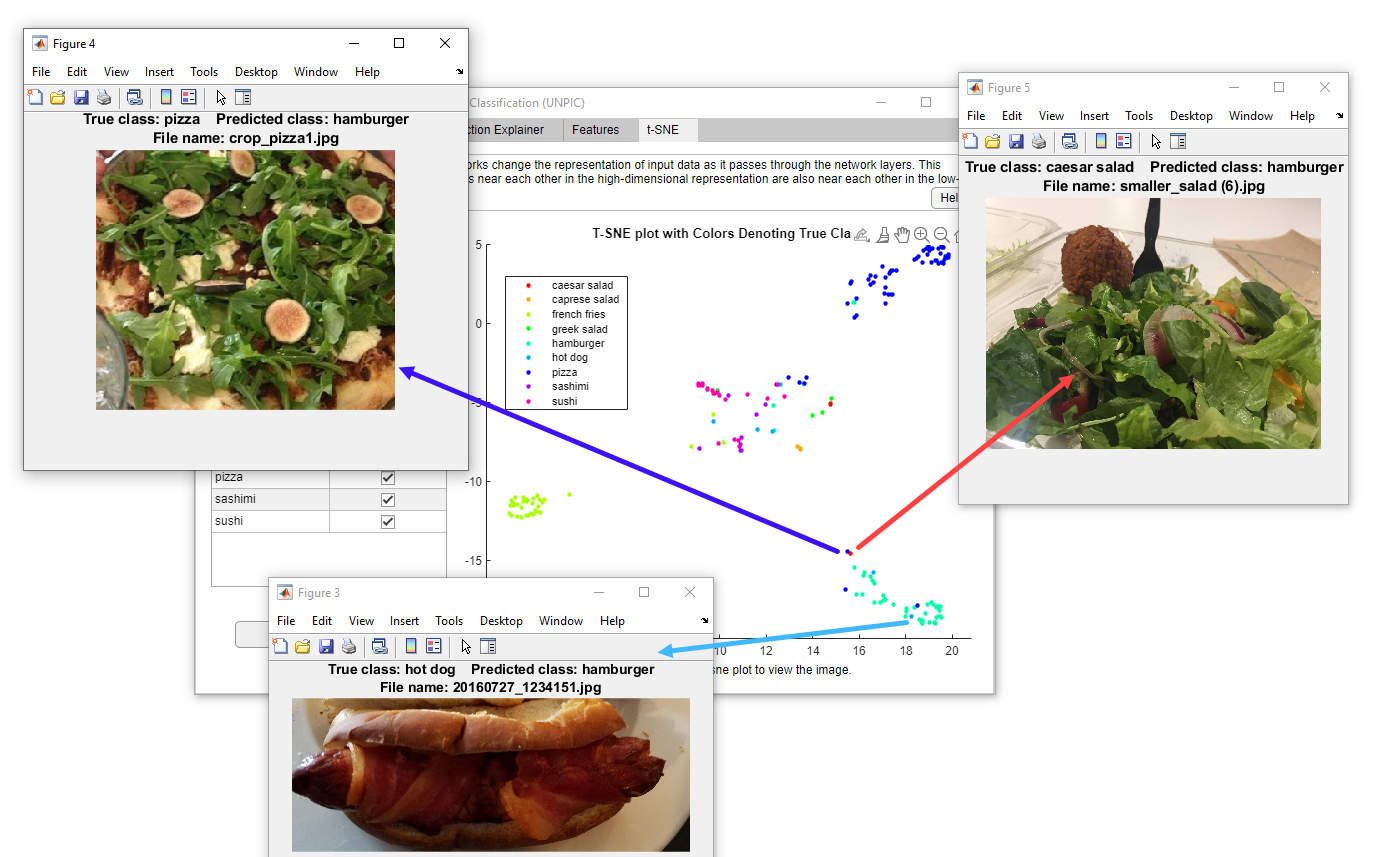

### Modify App using App Designer

To add to or modify the app, open it in App Designer. From here you can modify the app to further visualize the trained network.

appdesigner('UNPIC.mlapp')

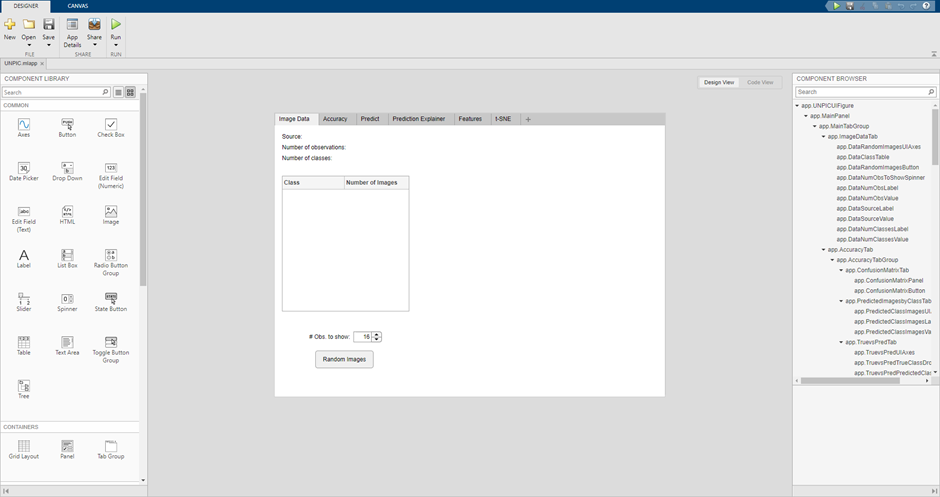

For example, you can add new visualization techniques or change the underlying settings. 

## References

[1] Zeiler M.D., Fergus R. (2014) Visualizing and Understanding Convolutional Networks. In: Fleet D., Pajdla T., Schiele B., Tuytelaars T. (eds) Computer Vision – ECCV 2014. ECCV 2014. Lecture Notes in Computer Science, vol 8689. Springer, Cham

[2] Selvaraju, R. R., M. Cogswell, A. Das, R. Vedantam, D. Parikh, and D. Batra. "*Grad-CAM: Visual Explanations from Deep Networks via Gradient-Based Localization.*" In IEEE International Conference on Computer Vision (ICCV), 2017, pp. 618–626. Available at [`Grad-CAM`](http://openaccess.thecvf.com/content_ICCV_2017/papers/Selvaraju_Grad-CAM_Visual_Explanations_ICCV_2017_paper.pdf) on the Computer Vision Foundation Open Access website.

[3] Simonyan, Karen, Andrea Vedaldi, and Andrew Zisserman. “Deep Inside Convolutional Networks: Visualising Image Classification Models and Saliency Maps.” *ArXiv:1312.6034 [Cs]*, April 19, 2014. [http://arxiv.org/abs/1312.6034.](https://arxiv.org/abs/1312.6034)

[4] *DeepDreaming with TensorFlow*. [https://github.com/tensorflow/docs/blob/master/site/en/tutorials/generative/deepdream.ipynb](https://github.com/tensorflow/docs/blob/master/site/en/tutorials/generative/deepdream.ipynb)

[5] van der Maaten, Laurens, and Geoffrey Hinton. "Visualizing Data using t-SNE." *Journal of Machine Learning Research 9,* 2008, pp. 2579–2605.

[6] *BVLC GoogLeNet Model*. [https://github.com/BVLC/caffe/tree/master/models/bvlc_googlenet](https://github.com/BVLC/caffe/tree/master/models/bvlc_googlenet)

## Helper Function

function downloadExampleFoodImagesData(url,dataDir)
% Download the Example Food Image data set, containing 978 images of
% different types of food split into 9 classes.

% Copyright 2019 The MathWorks, Inc.

fileName = "ExampleFoodImageDataset.zip";
fileFullPath = fullfile(dataDir,fileName);

% Download the .zip file into a temporary directory.
if ~exist(fileFullPath, "file")
    fprintf("Downloading MathWorks Example Food Image dataset...\n");
    fprintf("This can take several minutes to download...\n");
    websave(fileFullPath,url);
    fprintf("Download finished...\n");
else
    fprintf("Skipping download, file already exists...\n");
end

% Unzip the file.
%
% Check if the file has already been unzipped by checking for the presence
% of one of the class directories.
exampleFolderFullPath = fullfile(dataDir,"pizza");
if ~exist(exampleFolderFullPath, "dir")
    fprintf("Unzipping file...\n");
    unzip(fileFullPath,dataDir);
    fprintf("Unzipping finished...\n");
else
    fprintf("Skipping unzipping, file already unzipped...\n");
end
fprintf("Done.\n");

end

*Copyright 2020 The MathWorks, Inc.*